doxLevels = [0;10;50;100;250;500;1000;2000]';
abaLevels = [0;1;3;5;10;50;75;150]';
fluor_data = table2array(readtable('dox_aba_cell_ratios.csv'));
redAvg = fluor_data(:,9);
yellowAvg = fluor_data(:,10);
redAvgMat = reshape(redAvg, [8,8])';
yellowAvgMat = reshape(yellowAvg, [8,8])';
redHillParam=Hill2D(fluor_data(:,1:2), redAvg, 0, 1, 2, 3, 2, 3)

F = function_handle with value:
    @(z,xdata)z(1)+((z(2)*xdata(:,1).^z(3))./(z(4).^z(3)+xdata(:,1).^z(3))).*((z(6).^z(5))./(z(6).^z(5)+xdata(:,2).^z(5)))



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


z =     0.1391
    0.5739
    1.4385
   38.9593
    0.4173
   75.3615


redHillParam =     0.1391
    0.5739
    1.4385
   38.9593
    0.4173
   75.3615


flippedDoxAba = fliplr(fluor_data(:,1:2));
yellowHillParam=Hill2D(flippedDoxAba, yellowAvg, 0, 1, 50, 3, 2, 100)

F = function_handle with value:
    @(z,xdata)z(1)+((z(2)*xdata(:,1).^z(3))./(z(4).^z(3)+xdata(:,1).^z(3))).*((z(6).^z(5))./(z(6).^z(5)+xdata(:,2).^z(5)))



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


z =     0.0651
    0.7102
    2.3548
    1.6852
    0.4359
  637.5667


yellowHillParam =     0.0651
    0.7102
    2.3548
    1.6852
    0.4359
  637.5667


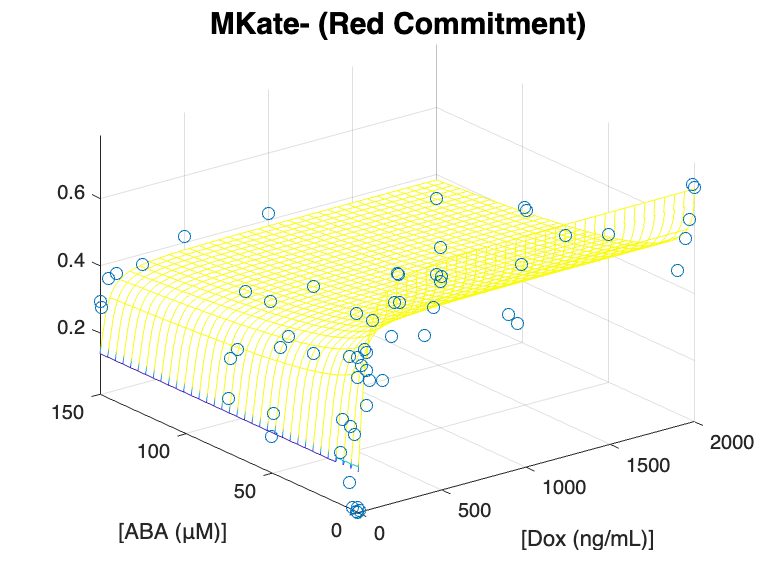

plot3dHill(fluor_data(:,9), fluor_data(:,1), fluor_data(:,2), doxLevels, abaLevels, redHillParam)
title('MKate- (Red Commitment)', 'FontSize', 15)
ylabel('[ABA (μM)]')
xlabel('[Dox (ng/mL)]')

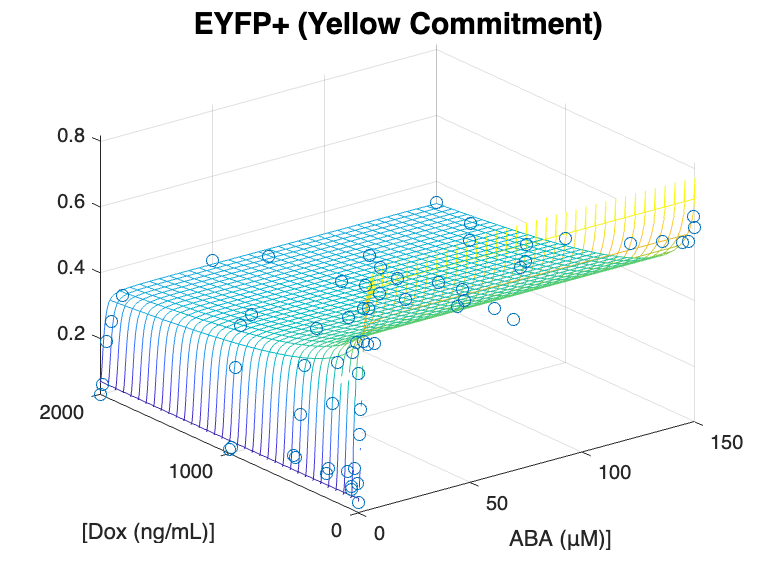

plot3dHill(fluor_data(:,10), fluor_data(:,2), fluor_data(:,1), abaLevels, doxLevels, yellowHillParam)
title('EYFP+ (Yellow Commitment)','FontSize', 15)
xlabel('ABA (μM)]')
ylabel('[Dox (ng/mL)]')

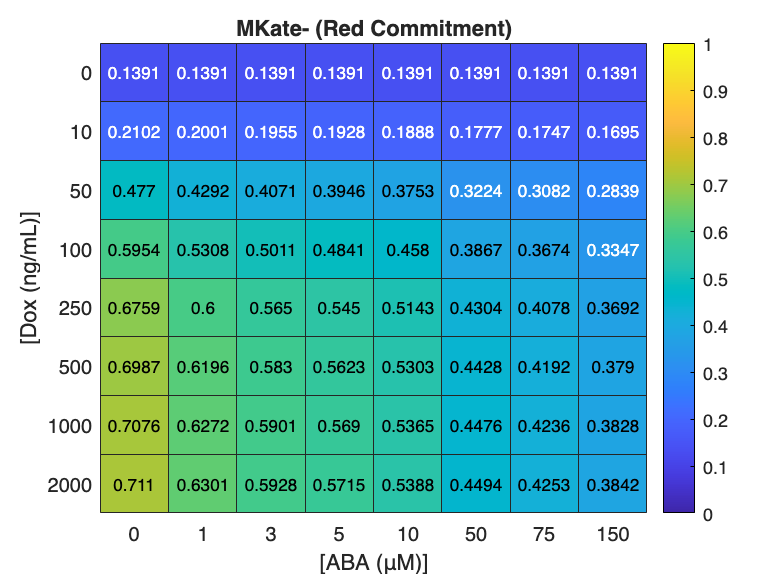

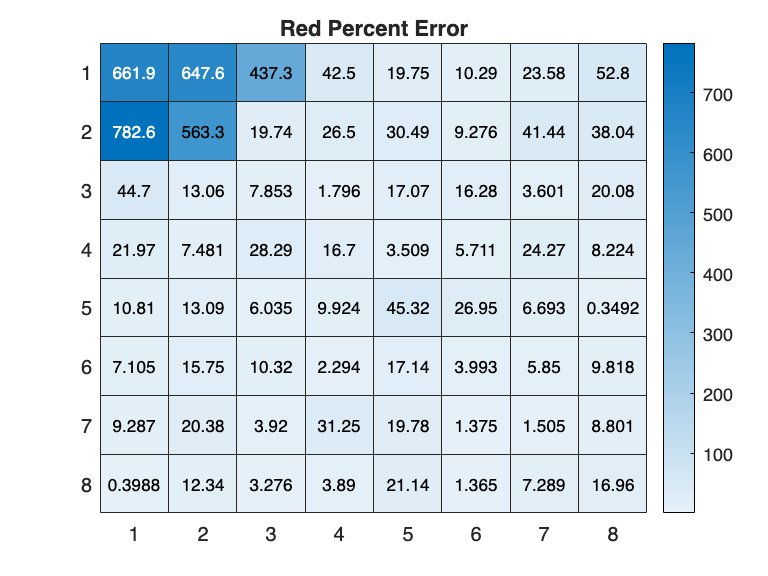

h4 =   HeatmapChart (Red Percent Error) with properties:

        XData: {8×1 cell}
        YData: {8×1 cell}
    ColorData: [8×8 double]

  Show all properties


redMSE = 0.0066

plotHeatmap(doxLevels, abaLevels, redHillParam, 'dox', redAvgMat);

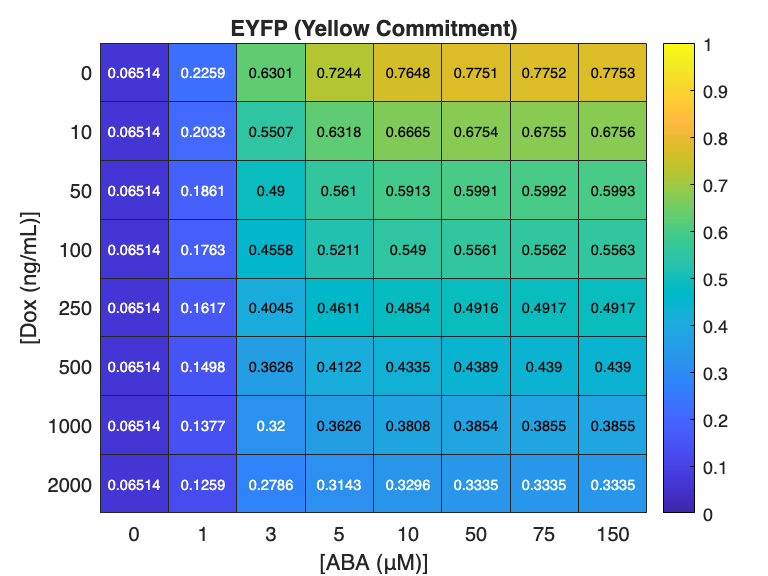

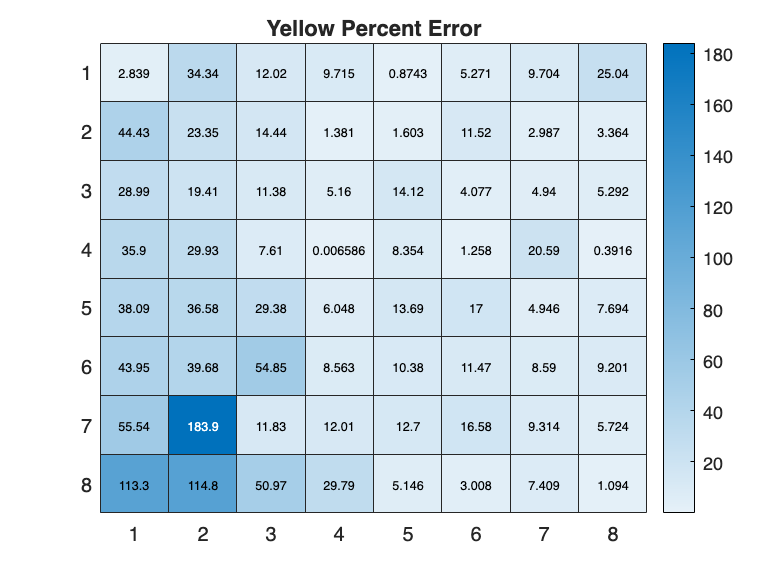

h3 =   HeatmapChart (Yellow Percent Error) with properties:

        XData: {8×1 cell}
        YData: {8×1 cell}
    ColorData: [8×8 double]

  Show all properties


yellowMSE = 0.0034

plotHeatmap(abaLevels, doxLevels, yellowHillParam, 'aba', yellowAvgMat);